# Gridded MetCoOp-Ensemble Prediction System data: automated and remote data extraction

The data from MEPS (MetCoOp-Ensemble Prediction System) [1] are extracted from the *THREDDS* Data Server of the  Norwegian Meteorological Institute [2]. The data source are netcdf files and the OPeNDAP framework is used to read the data without downloading them.  The data are resampled as gridded data. The time resolution is 1 h and the horizontal resolution is ca. 1 km.

**References**

[1] [https://www.met.no/en/projects/metcoop](https://www.met.no/en/projects/metcoop) 

[2] [https://thredds.met.no](https://thredds.met.no)  

## Definition of the parameters

Data from storm Aina (2017-12-08) at 4 am are extracted.

targetYear = 2017; 
targetMonth = 12;
targetDay = 08;
targetHour = 4;

resolution = 0.01; % resolution for latitude and longitude in degrees
targetLat = [53 73]; % target latitude (between 52 and 74)
targetLon = [3 30];  % target longitude (between -11 and 42)


type = 'rerun version 2'; % 3 choices: 'Operational', 'rerun version 2' or 'rerun version 1'


% Total list of data to extract
% output = {'land_area_fraction','wind_speed_10m','wind_direction_10m',...
%     'relative_humidity_2m','precipitation_amount',...
%     'integral_of_surface_downwelling_shortwave_flux_in_air_wrt_time',...
%     'air_pressure_at_sea_level','air_temperature_2m','cloud_area_fraction'};

% reduced list
output = {'land_area_fraction','wind_speed_10m','air_temperature_2m'};


## Extract the data on the 2017-12-08 at 4 am for Scandinavia

% Grid definition
[lon,lat] = meshgrid(targetLon(1):resolution:targetLon(end),targetLat(1):resolution:targetLat(end));
[Nlat,Nlon]=size(lat);
% Preallocate the output
Ntot = numel(targetYear)*numel(targetMonth)*numel(targetDay)*numel(targetHour);
U = NaN(Ntot,Nlat,Nlon); % wind_speed_10m
LAF= NaN(Ntot,Nlat,Nlon);% land_area_fraction
T= NaN(Ntot,Nlat,Nlon);% air_temperature_2m
% DD = NaN(Ntot,Nlat,Nlon); % wind_direction_10m
% RH = NaN(Ntot,Nlat,Nlon);% relative_humidity_2m
% P= NaN(Ntot,Nlat,Nlon);% air_pressure_at_sea_level

oo= 1;
for ii=1:numel(targetYear)
    for jj=1:numel(targetMonth)
        for kk=1:numel(targetDay)
            for ll=1:numel(targetHour)
                tic
                [data] = MET3P(targetLat,targetLon,...
                    targetYear(ii),targetMonth(jj),targetDay(kk),...
                    targetHour(ll),type,output,resolution);
                U(oo,:,:)= data.U';
                LAF(oo,:,:) = data.LAF';
                T(oo,:,:)= data.T';
                oo=oo+1;
                toc
            end
        end
    end
end

Elapsed time is 148.930726 seconds.


## Wind speed map

Only display data above the ocean

ii= 1

ii = 1

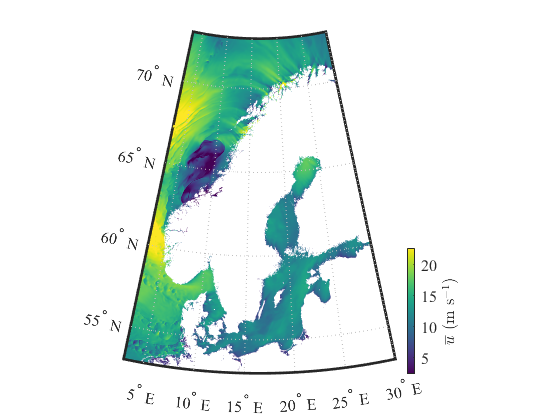

clf;close all;
figure
myU = squeeze(U(ii,:,:));
myLAF = squeeze(LAF(ii,:,:));
myU(myLAF>0.5)=nan;
hold off

if  license('test','MAP_Toolbox')
    worldmap(targetLat,targetLon)
    geoshow(lat,lon,myU, 'DisplayType','surface')
    
else
    imagesc(lon(1,:),lat(:,1),myU);axis xy
end
hold on


if exist('viridis.m','file')
    colormap('viridis');
else
    colormap('hot');
end
caxis([quantile(reshape(U,1,[]),0.01) quantile(reshape(U,1,[]),0.99)])
if ii==1 || ~isvalid(cb2),
    cb2 = colorbar('location','eastoutside');
end
set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')

x1=get(gca,'position');x=get(cb2,'Position');x(3)=0.015; x(4)=0.3;set(cb2,'Position',x);set(gca,'position',x1)
cb2.Label.String = '$\overline{u}$ (m s$^{-1}$)';
cb2.Label.Interpreter = 'latex';
cb2.AxisLocation = 'out';

set(gcf,'color','w')

## Air temperature map

Display data both above the ocean and above land

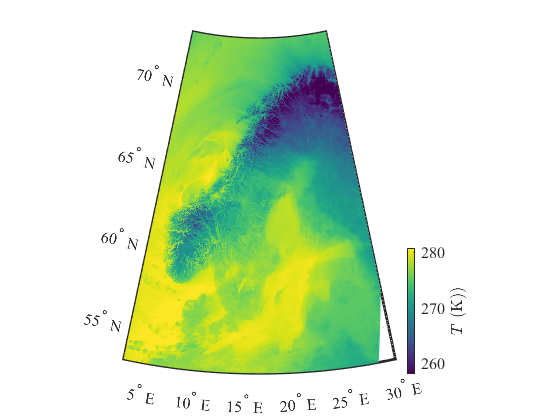

figure
myT = squeeze(T(ii,:,:));
hold off

if  license('test','MAP_Toolbox')
    worldmap(targetLat,targetLon)
    geoshow(lat,lon,myT, 'DisplayType','surface')
    
else
    imagesc(lon(1,:),lat(:,1),myT);axis xy
end
hold on


if exist('viridis.m','file')
    colormap('viridis');
else
    colormap('hot');
end
caxis([quantile(reshape(T,1,[]),0.01) quantile(reshape(T,1,[]),0.99)])
if ii==1 || ~isvalid(cb2)
    cb2 = colorbar('location','eastoutside');
end
set(findall(gcf,'-property','FontSize'),'FontSize',12,'FontName','Times')

x1=get(gca,'position');x=get(cb2,'Position');x(3)=0.015; x(4)=0.3;set(cb2,'Position',x);set(gca,'position',x1)
cb2.Label.String = '$T$ (K))';
cb2.Label.Interpreter = 'latex';
cb2.AxisLocation = 'out';

set(gcf,'color','w')